# Fault Location Classification of the IEEE 123 Node Test Feeder

Copyright © 2026, The MathWorks, Inc.

## Introduction

The workflow described in this document programmatically steps through fault sequences on each three-phase bus, two-phase bus and single-phase bus in the IEEE 123 Node Test Feeder. There are 70 three-phase buses, with 7 fault sequences possible per bus, giving a total of 490 faults for the three-phase buses. There are 3 two-phase buses, with 3 fault sequences possible per bus, giving a total of 9 faults for the two-phase buses. There are 55 single-phase buses, with 1 fault sequence possible per bus, giving a total of 55 faults for the single-phases buses. Overall, there are a total of 554 fault sequences in the system. The workflow is extended to consider different fault resistances and uses parallel computing to distribute the scenarios.

Uses MathWorks Release R2025b,

MATLAB®

Simulink®

Simscape™

Simscape™ Electrical™

Statistics and Machine Learning Toolbox™ (for classificationLearner)

## IEEE 123 Node Test Feeder Model

Run *create_IEEE_123_EMT_faults.mlx* before running this script.

Open the top-level model

bdclose all
clear
load data123faults
open_system('top_level_faults')

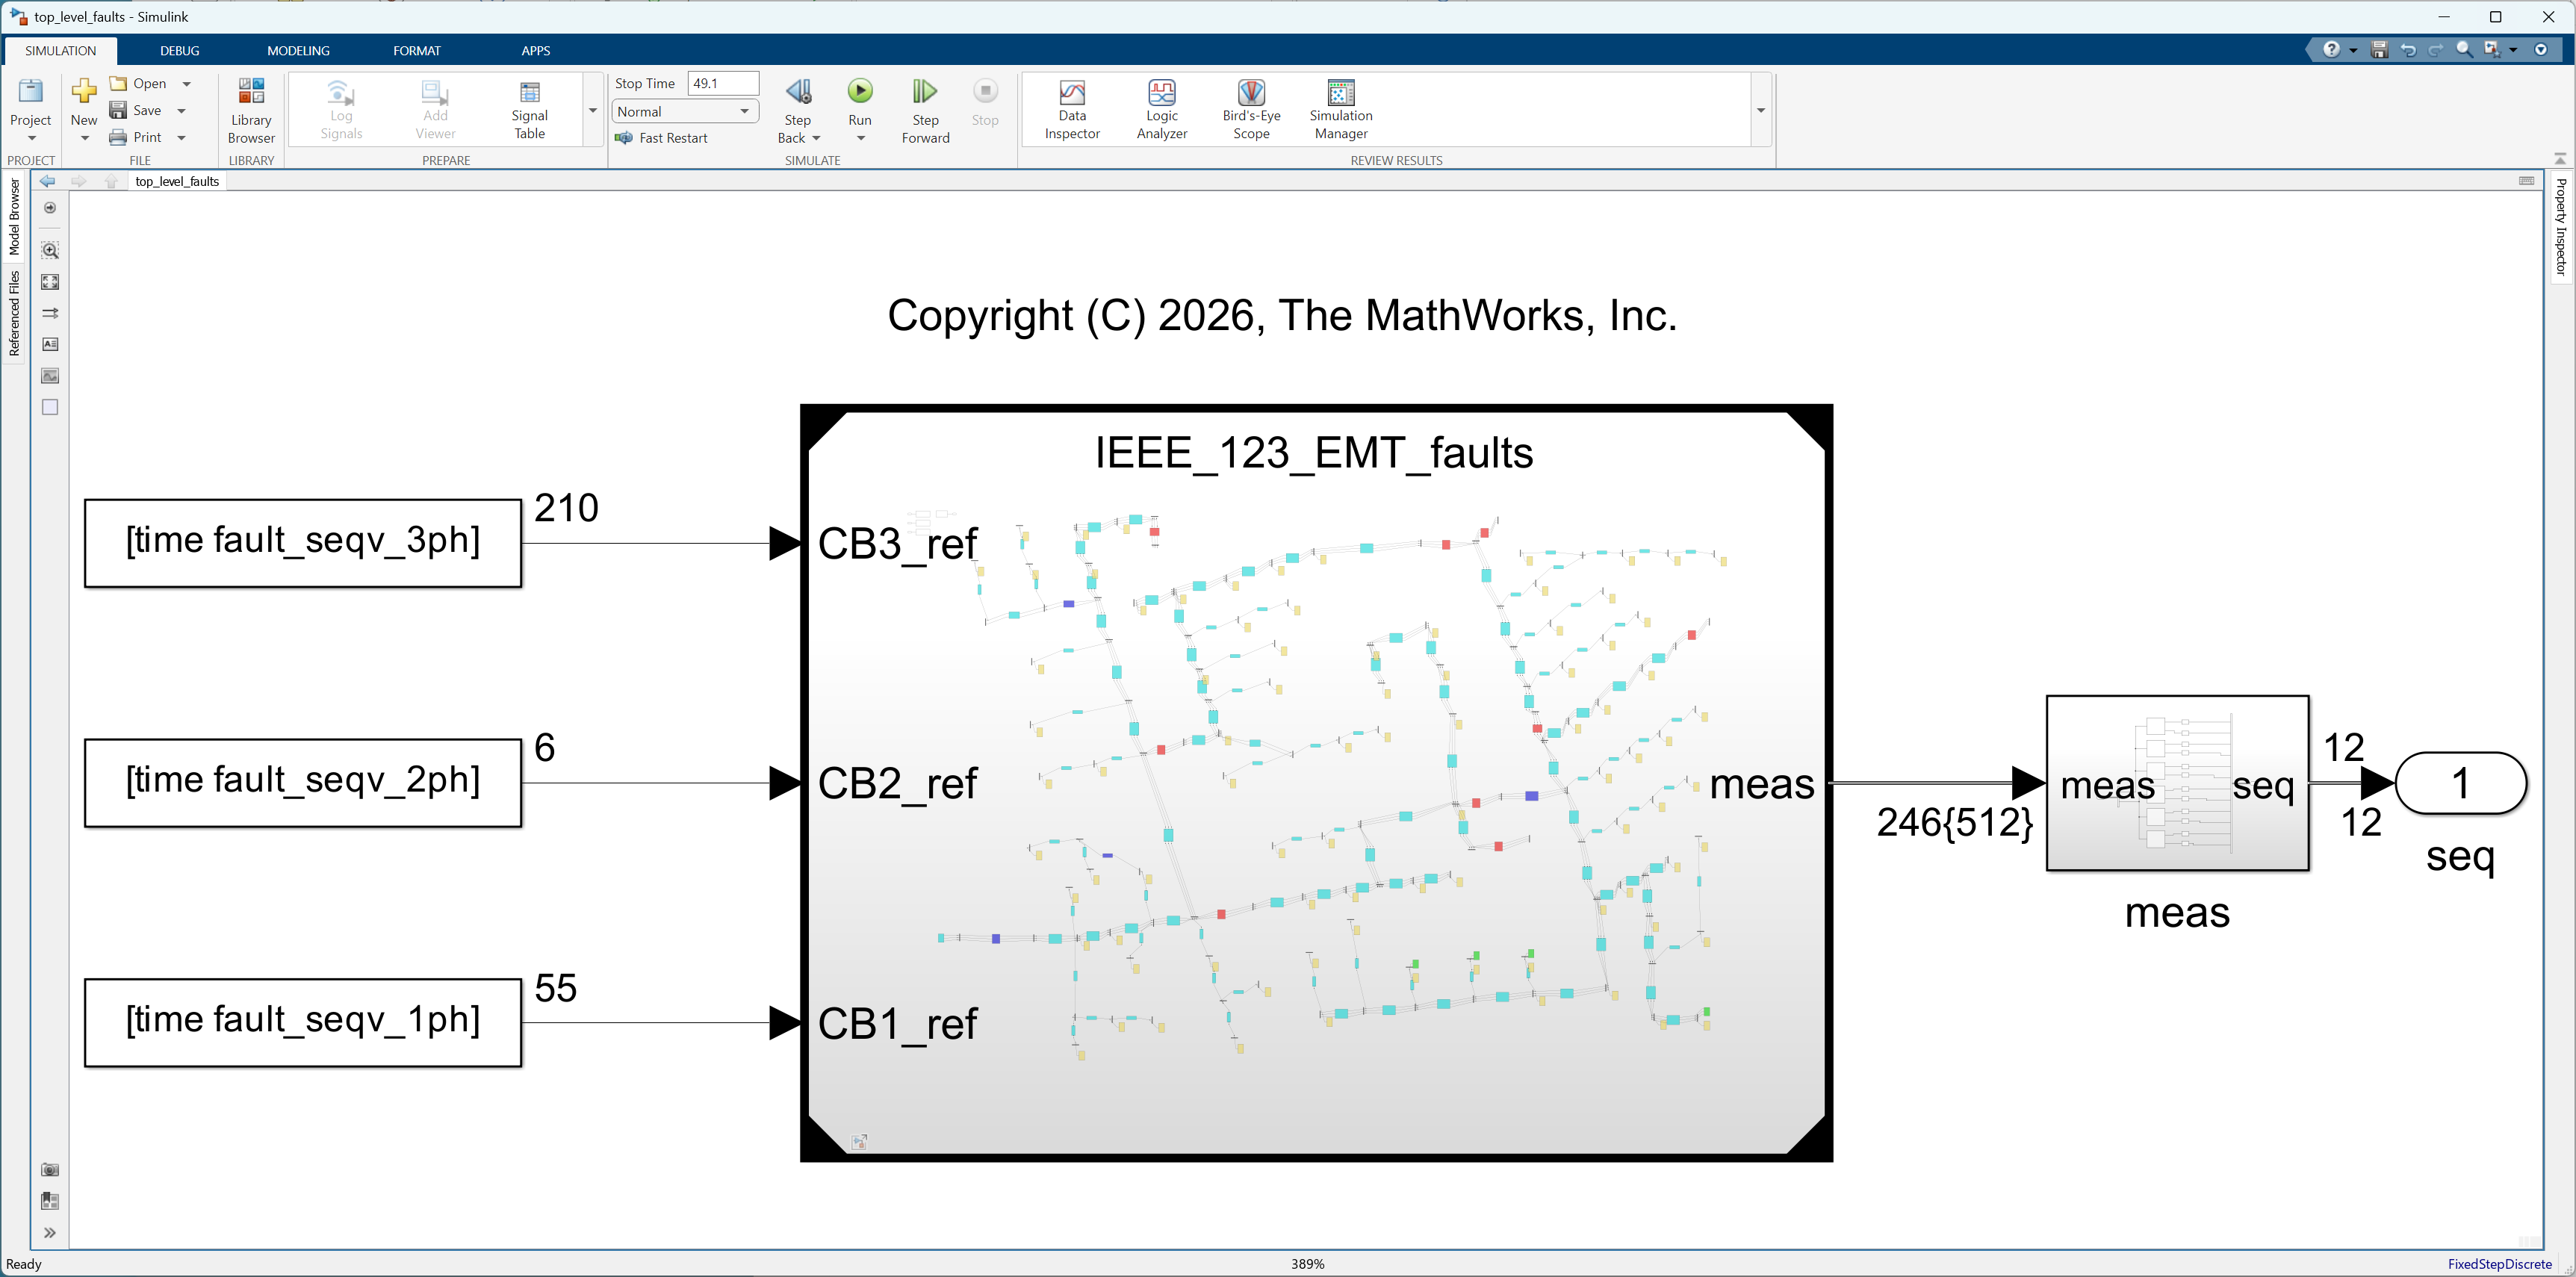 

The input to CB3_ref dictates the faults being applied to the three-phases buses and is defined by fault_seqv (see below). Note that we 271 fault locations in total for the full system. The CB2_ref input is for faulting the two-phase buses, and the CB1_ref input is for faulting the single-phase buses). We want to explore whether a minimal amout of system measurements contains enough information to identify the location and type of a given fault. In this example, we choose voltage at bus 13 and current through line 1_7. As we are generating EMT waveforms in an unbalanced system, we calculate so called symmetrical components, to convert the EMT waveforms into vector values that characterize the nature of the imbalance. The zero-order hold is in place to pick off the steady-state value of each fault (that occurs every 0.1s).

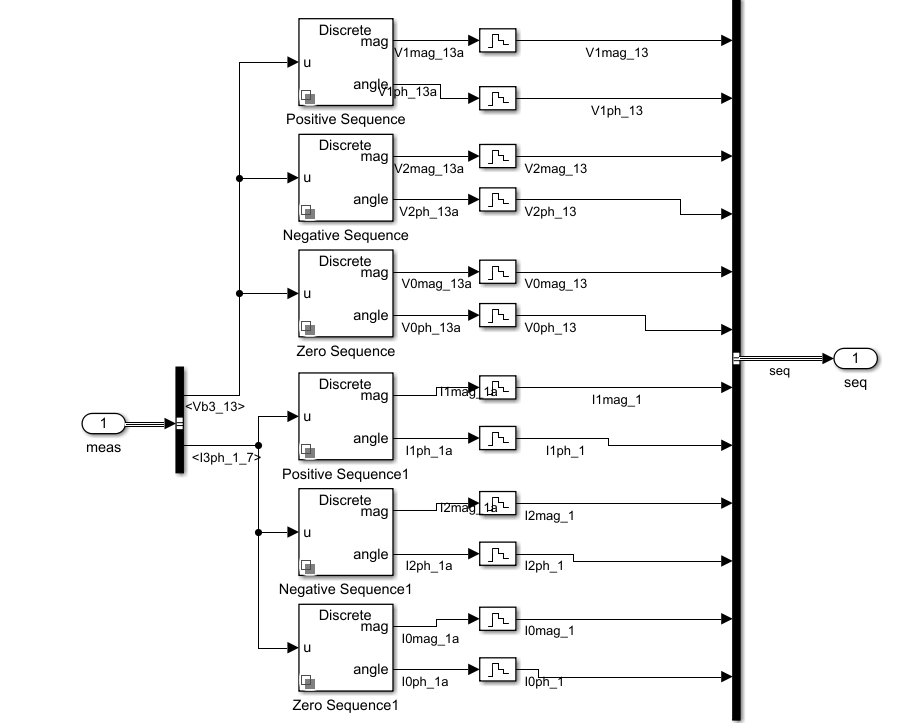

## Three-Phase Fault Definition

Create fault scenarios, where each bus is faulted in sequence

fault_seq3 = [0 1 1   % a-g fault
              1 0 1   % b-g fault
              1 1 0   % c-g fault
              0 0 1   % a-b-g fault
              0 1 0   % a-c-g fault
              1 0 0   % b-c-g fault
              0 0 0]; % a-b-c-g fault

num_buses3 = 70;

fault_seqv3a = ones(7*num_buses3,3*num_buses3);

for x3 = 1:num_buses3

    fault_seqv3a(7*(x3-1)+(1:7),3*(x3-1)+(1:3)) = fault_seq3;

end

fault_seqv3a = [ones(1,210);fault_seqv3a]; % add unfaulted response at the start

% apply each fault every 0.1 seconds.

time3 = (0.06:0.1:size(fault_seqv3a,1)/10)';


## Two-Phase Fault Definition

fault_seq2 = [0 1   % a-g fault
              1 0   % b-g fault
              0 0]; % a-b-g fault

num_buses2 = 3;

fault_seqv2a = ones(3*num_buses2,2*num_buses2);

for x2 = 1:num_buses2

    fault_seqv2a(3*(x2-1)+(1:3),2*(x2-1)+(1:2)) = fault_seq2;

end

% apply each fault every 0.1 seconds.

time2 = size(fault_seqv3a,1)/10 + (0.06:0.1:size(fault_seqv2a,1)/10)';

## Single-Phase Fault Definition

fault_seq1 = 0;   % a-g fault

num_buses1 = 55;

fault_seqv1a = ones(num_buses1,num_buses1);

for x1 = 1:num_buses1

    fault_seqv1a(x1,x1) = fault_seq1;

end

% expand fault sequences across the entire time-scale

fault_seqv_3ph = [fault_seqv3a;ones((size(fault_seqv2a,1)+size(fault_seqv1a,1)),size(fault_seqv3a,2))];
fault_seqv_2ph = [ones((size(fault_seqv3a,1)),size(fault_seqv2a,2));fault_seqv2a;ones((size(fault_seqv1a,1)),size(fault_seqv2a,2))];
fault_seqv_1ph = [ones((size(fault_seqv3a,1)+size(fault_seqv2a,1)),size(fault_seqv1a,2));fault_seqv1a];

% apply each fault every 0.1 seconds.

time = [time3;time2;((size(fault_seqv3a,1)+ size(fault_seqv2a,1))/10 + (0.06:0.1:size(fault_seqv1a,1)/10)')];

## Simulate Fault Scenarios

Here we are running 3 set of fault resistance parameters. This is where parallel computing can be used to generate a range of fault data. Set num_sims to a higher value to cover a larger range of fault resistances. Change Ronv and Rgv as appropriate.

num_sims = 3;

Ronv = logspace(-5,-1,num_sims);
Rgv  = logspace(-5,-5,num_sims);

model = 'top_level_faults'; 

for x = 1:num_sims

    in1(x) = Simulink.SimulationInput(model); %#ok<*SAGROW> 
    in1(x) = in1(x).setVariable('Ron',Ronv(x));
    in1(x) = in1(x).setVariable('Rg',Rgv(x));
    in1(x) = in1(x).setModelParameter('StopTime','55.5');
  
end

tic
out = parsim(in1,'ShowProgress','on','TransferBaseWorkspaceVariables','on'); %#ok<*XFRWSP>

[05-Mar-2026 07:46:01] Checking for availability of parallel pool...
[05-Mar-2026 07:46:01] Starting Simulink on parallel workers...
[05-Mar-2026 07:46:02] Loading project on parallel workers...
[05-Mar-2026 07:46:02] Configuring simulation cache folder on parallel workers...
[05-Mar-2026 07:46:02] Transferring base workspace variables used in the model to parallel workers...
[05-Mar-2026 07:46:02] Total size of base workspace variables to send to parallel workers is 139.03 MB.
[05-Mar-2026 07:46:02] Loading model on parallel workers...
[05-Mar-2026 07:46:11] Running simulations...
[05-Mar-2026 08:11:09] Completed 1 of 3 simulation runs
[05-Mar-2026 08:11:09] Received simulation output (size: 25.47 MB) for run 1 from parallel worker.
[05-Mar-2026 08:11:27] Completed 2 of 3 simulation runs
[05-Mar-2026 08:11:27] Received simulation output (size: 25.47 MB) for run 2 from parallel worker.
[05-Mar-2026 08:11:27] Completed 3 of 3 simulation runs
[05-Mar-2026 08:11:27] Received simulation ou

toc

Elapsed time is 1528.123776 seconds.


## Create Table with Fault Classifications

% classification
fclass3 = [{'_a_g'};{'_b_g'};{'_c_g'};{'_a_b_g'};{'_a_c_g'};{'_b_c_g'};{'_a_b_c_g'}];
fclass2 = [{'_a_g'};{'_b_g'};{'_a_b_g'}];
fclass1 =  {'_a_g'};

fault_class = [];
for x3 = 1:numel(tag3)
    fault_class = [fault_class;strcat(tag3(x3),fclass3)]; %#ok<*AGROW>
end

for x2 = 1:numel(tag2)
    fault_class = [fault_class;strcat(tag2(x2),fclass2)]; %#ok<*AGROW>
end

for x1 = 1:numel(tag1)
    fault_class = [fault_class;strcat(tag1(x1),fclass1)]; %#ok<*AGROW>
end

fault_class = [{'unfaulted'};fault_class];

fault_class = categorical(fault_class);

T = [];

for xm = 1:num_sims

% Bus 13 voltage
V1mag_13 = out(xm).yout{1}.Values.V1mag_13.Data(2:end); % positive-sequence magnitude
V1ph_13  = out(xm).yout{1}.Values.V1ph_13.Data(2:end);  % positive-sequence angle
V2mag_13 = out(xm).yout{1}.Values.V2mag_13.Data(2:end); % negative-sequence magnitude
V2ph_13  = out(xm).yout{1}.Values.V2ph_13.Data(2:end);  % negative-sequence angle
V0mag_13 = out(xm).yout{1}.Values.V2mag_13.Data(2:end); % zero-sequence magnitude
V0ph_13  = out(xm).yout{1}.Values.V2ph_13.Data(2:end);  % zero-sequence angle

% Line 1-7 current
I1mag_1 = out(xm).yout{1}.Values.I1mag_1.Data(2:end);   % positive-sequence magnitude
I1ph_1  = out(xm).yout{1}.Values.I1ph_1.Data(2:end);    % positive-sequence angle
I2mag_1 = out(xm).yout{1}.Values.I2mag_1.Data(2:end);   % negative-sequence magnitude
I2ph_1  = out(xm).yout{1}.Values.I2ph_1.Data(2:end);    % negative-sequence angle
I0mag_1 = out(xm).yout{1}.Values.I0mag_1.Data(2:end);   % zero-sequence magnitude
I0ph_1  = out(xm).yout{1}.Values.I0ph_1.Data(2:end);    % zero-sequence angle

T = [T;table(V1mag_13,V1ph_13,V2mag_13,V2ph_13,V0mag_13,V0ph_13,I1mag_1,I1ph_1,I2mag_1,I2ph_1,I0mag_1,I0ph_1,fault_class)];

end

## Classification

This section uses a subset of the data in the classificationLeaner app.

c1 = categories(T.fault_class);    % fault categories
c2 = c1(end-19:end);               % select the last 20 categories 
idx = ismember(T.fault_class,c2);  % index into the categories
T1 = T(idx,:);                     % create a table

Open the classificationLearner app, load table T1, and select All Quick-To-Train.

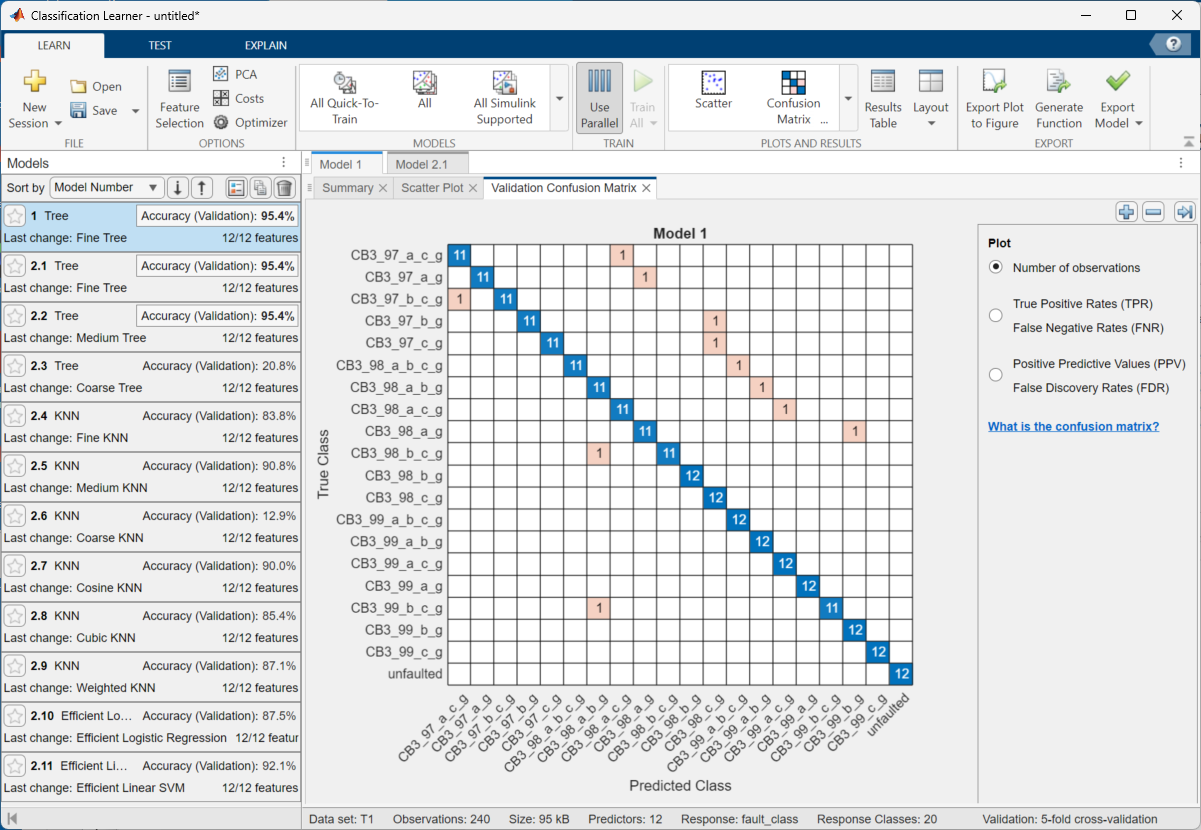

END OF DOCUMENT